%load("data.mat")
time=0:10;%for intial 10 days
%so propagate ode on interval [0,1]
%and fit it against the first day
p_intial=rand
%p_intial = [0.0001 0.0001 0.0001 0.0001 0.0001 0.0001 0.0001 0.0001 0.0001 0.0001 0.0001 0.0001 0.0001 0.0001 0.0001 0.0001 ];
p_intial = [0.001 0.001 0.001 0.001 0.001 0.001 0.001 0.001 0.001 0.001 0.001 0.001 0.001 0.001 0.001 0.001 ];%intial parameter values to start
[p,Rsdnrm,Rsd,ExFlg,OptmInfo,Lmda,Jmat] = lsqcurvefit(@MonodKinetics1,p_intial',time',combined_tranposed(:,1:10));%apply curve fit using lsqcurvefit and estimate parameter values (p) which fit the real data the best.


Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>


%simulation of the ode with the estimated parameters (p) selected
%according to the local minimum

Mfit = MonodKinetics1(p,time);
figure
s=stackedplot(Mfit')%plotting the simulated result

s =   StackedLineChart with properties:

            XData: [1 2 3 4 5 6 7 8 9 10]
            YData: [10×5 double]
    DisplayLabels: {5×1 cell}
            Color: [0 0.4470 0.7410]
        LineStyle: '-'
        LineWidth: 0.5000
           Marker: 'none'
       MarkerSize: 6

  Show all properties


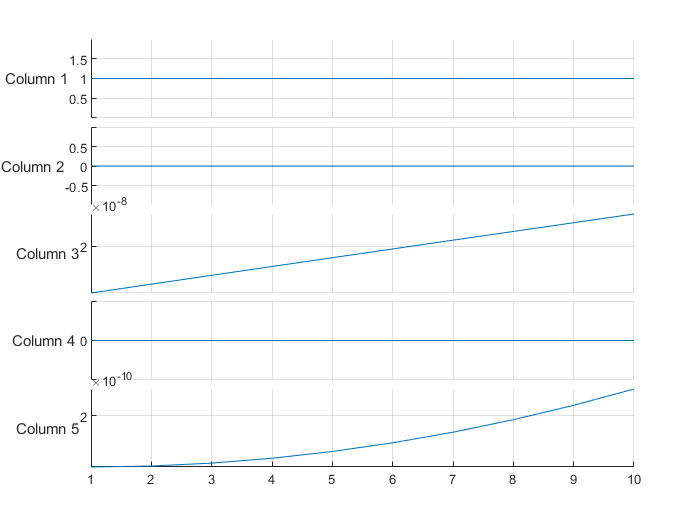

grid

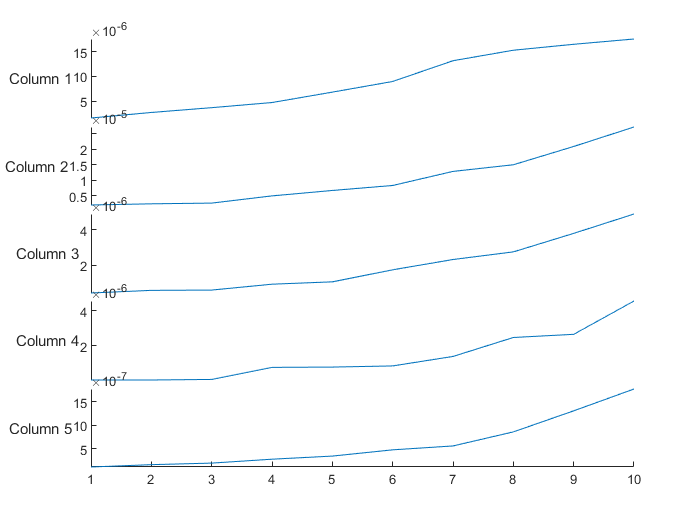

s =   StackedLineChart with properties:

            XData: [1 2 3 4 5 6 7 8 9 10]
            YData: [10×5 double]
    DisplayLabels: {5×1 cell}
            Color: [0 0.4470 0.7410]
        LineStyle: '-'
        LineWidth: 0.5000
           Marker: 'none'
       MarkerSize: 6

  Show all properties




figure
s=stackedplot(combined_tranposed(:,1:10)')%ploting the actual data 

%column 1= dignosed 
%column 2= recognised
%column 3=threatened
%column 4=healing
%column 5= extinct
%fo some reason when I transpose the matrix the rownales diappear (will fix
%that).